clear all
syms x1(t) x2(t) y1(t) y2(t) theta1(t) theta2(t) F1x(t) F1y(t) F2x(t) F2y(t) F3x(t) F3y(t)
%Try adding two forcing terms. 
m1=4; m2=2;L=3; 

IG1=1/12*m1*L^2; IG2=1/12*m2*L^2;

rG1=[x1(t);y1(t)];
rG2=[x2(t);y2(t)];
F1=[F1x(t);F1y(t)];
F2=[F2x(t);F2y(t)];
F3=[F3x(t);F3y(t)];
g=9.81;

%Forces 1 and 2 act on the top arm, Force 3 on the bottom arm. 

%F=ma for top arm
eq1=m1*diff(rG1,t,t)==F1+F2-m1*g*[0;1];
MF1G1=cross(-[rG1;0],[F1;0]);
MF2G1=cross([rG1;0],[F2;0]);
%IG theta''=M for the top arm
eq2=IG1*diff(theta1(t),t,t)==MF1G1(3)+MF2G1(3)+cos(4*t); % <-- forcing term 1 here. 

%F=ma for the bottom arm.
eq3=m2*diff(rG2,t,t)==F3-m2*g*[0;1];
%IG theta''=M for the bototm.
MF3G2=cross(L/2*[-sin(theta2(t));cos(theta2(t));0],[F3;0]) ;  
eq4=IG2*diff(theta2(t),t,t)==MF3G2(3)+ 4*sin(3*t);% <-- forcing 2 here.

%Keep top arm anchored at origin. 
eq5=rG1+L/2*[-sin(theta1(t));cos(theta1(t))]==[0;0];
%Keep top arm and bottom arm attached. 
eq6=rG1+L/2*[sin(theta1(t));-cos(theta1(t))]==rG2+L/2*[-sin(theta2(t));cos(theta2(t))];
%F2 and F3 must be related. 
eq7=F2==-F3;


%As usual, set up equations of motion.  NOTICE THE CONSTITUATIVE RELATION
%F2==-F3 goes in the DEs!  This is because that equation doesn't need to be
%differentiated.  Maybe we should do something about that for clarity?

DES=[eq1;eq2;eq3;eq4;eq7];
PositionConstraints=[eq5;eq6];

%Solve the thing with the DAE solver. 
soln=mechanicsAsDAE(DES,PositionConstraints,[],[0,10],{theta1==0, diff(theta1)==0,theta2==0,diff(theta2)==0},[],0);

The unknown functions (just the base functions, not derivatives) are: F1x(t),F2x(t),F3x(t),F1y(t),F2y(t),F3y(t),theta1(t),theta2(t),x1(t),x2(t),y1(t),y2(t)
Initial Conditions:
Y0/YP0:
F1x: 0.454545 F1xt:0.000000
F2x: -0.090909 F2xt:0.000000
F3x: 0.090909 F3xt:0.000000
F1y: 58.860000 F1yt:0.000000
F2y: -19.620000 F2yt:0.000000
F3y: 19.620000 F3yt:0.000000
theta1: 0.000000 theta1t:0.000000
theta2: 0.000000 theta2t:0.000000
x1: 0.000000 x1t:0.000000
x2: 0.000000 x2t:0.000000
y1: -1.500000 y1t:0.000000
y2: -4.500000 y2t:0.000000
Dtheta1t: 0.000000 Dtheta1tt:0.060606
Dtheta2t: 0.000000 Dtheta2tt:-0.090909
Dx1t: 0.000000 Dx1tt:0.090909
Dx2t: 0.000000 Dx2tt:0.045455
Dy1t: 0.000000 Dy1tt:-0.000000
Dy2t: 0.000000 Dy2tt:0.000000


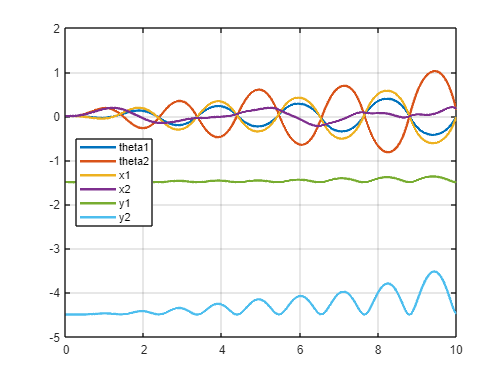

plot(soln.t,soln.theta1,soln.t,soln.theta2,soln.t,soln.x1,soln.t,soln.x2,soln.t,soln.y1,soln.t,soln.y2,'LineWidth',2); grid on; legend({"theta1","theta2","x1","x2","y1","y2"},'Location',"best");